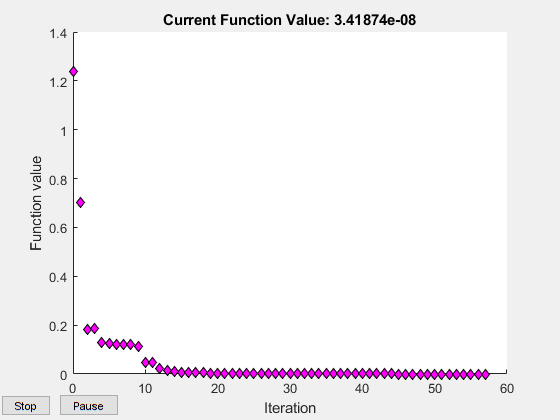


Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.



%Run the simulation over double support. Find the starting and ending
%points. Generate a curve that connects them in swing phase.
clear all
path(pathdef)
addpath(genpath('Experiments'))
addpath(genpath('Analysis'))
addpath(genpath('UtilityFunctions'))
addpath(genpath('Model'))

global flowdata

flowdata = flowData;

%Simulation parameters
flowdata.Parameters.Environment.slope = 0;   %ground slope
flowdata.Parameters.dim = 14;        %state variable dimension
flowdata.Parameters.Environment.g = 9.81;

Mtor = 40;      %kg 
Mth = 10;        %kg 
Ms = 5;         %kg 
Itorz = 0;     %kg m^2
Ithz = 0;       %kg m^2
Isz = 0;        %kg m^2
ltor = 0.5;    %m
lth = 0.5;      %m
ls = 0.5;       %m
rtor = 0.25/2;  %m
rth = 0.5/2;    %m
rs = 0.5/2;     %m
flowdata.Parameters.Biped.asvec =[Mtor Mth Ms Itorz Ithz Isz ltor lth ls rtor rth rs 9.81];

%Trajectory
load('slip_walk.mat') 
pf1 = out_extra.steps{1}.phases{2}.foot_pos_1;
pf2 = out_extra.steps{1}.phases{2}.foot_pos_2;
indexi = find(tout==out_extra.steps{1}.phases{2}.tstart,1);
indexf = find(tout==out_extra.steps{1}.phases{2}.tend,1);
zs = xout(indexi,:);
zf = xout(indexf,:);

%fmincon Optimization to solve inverse kinematic problem at the end of SLIP
%Double Support (mapping SLIP cords into Flat Foot Biped cords)
dim = flowdata.Parameters.dim;
A=[];
b=[];

%Constrain stance heel to ground
Aeq = zeros(4,14);
Aeq(1,1) = 1;
Aeq(2,2) = 1;
Aeq(3,8) = 1;
Aeq(4,9) = 1;
beq = zs';
x0 = zeros(1,14);
x0(3) = pi/4;
%Bounded the joints to be +- 90 degree rotation from initial condition
lb = -[pi/2*ones(1,7),inf(1,7)];
ub = [pi/2*ones(1,7),inf(1,7)];

options = optimoptions('fmincon','MaxFunctionEvaluations',10000,'OptimalityTolerance',1e-15,'Display','final-detailed','PlotFcn','optimplotfval');
cost_fun = @(x)IK_SLIP_pos_cost(x,pf1,pf2);
[xs_1,fval] = fmincon(cost_fun,x0,A,b,Aeq,beq,lb,ub,[] ,options);

play_handels_messiah

%find velocities
f = @(v)IK_SLIP_vel_cost([xs_1(1:9),v])

f = function_handle with value:
    @(v)IK_SLIP_vel_cost([xs_1(1:9),v])


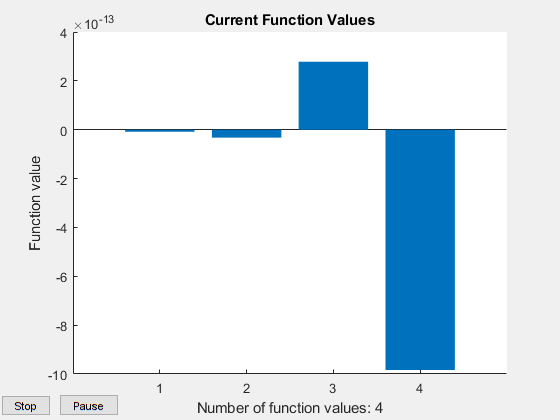


Equation solved. The sum of squared function values, r = 1.045557e-24, is less
than sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of
r, 1.304111e-13, is less than 1e-4*options.OptimalityTolerance = 1.000000e-10.



v0 = zeros(1,5);
options = optimoptions('fsolve','Display','final-detailed','PlotFcn','optimplotfval','MaxFunctionEvaluations',100000,'MaxIterations',4e3);
v_star = fsolve(f,v0,options);

xs_3 = [xs_1(1:9),v_star];
play_handels_messiah

xi_slip_dsupp=xs_3;
dir_path = pwd;
save(strcat(dir_path,'\Experiments\InvKinOpt\xi_slip_dsupp.mat'),'xi_slip_dsupp');

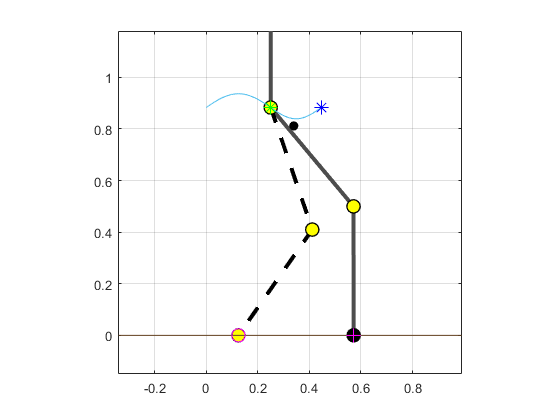

%plot results
figure;
drawBiped(xs_3','na');

hold on
plot(xout(:,1),xout(:,2))
plot(zs(1),zs(2),'g*','MarkerSize',10)
plot(zf(1),zf(2),'b*','MarkerSize',10)
plot(pf1(1),pf1(2),'m+','MarkerSize',10)
plot(pf2(1),pf2(2),'mo','MarkerSize',10)

xlim([-0.34 0.99])
ylim([-0.15 1.18])

drawBiped(xi_slip_dsupp','na');

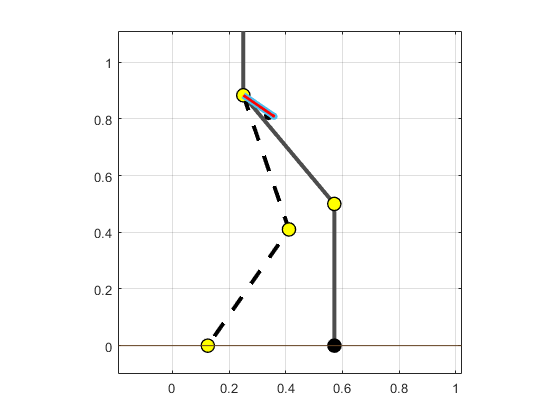


quiver(zs(1),zs(2),zs(3),zs(4), 1/10,'LineWidth',5)
params = flowdata.Parameters.Biped.asvec;
hip_vel= Hip_vel_func(xi_slip_dsupp',params);
hip_vel = hip_vel(1:2,4);

quiver(zs(1),zs(2),hip_vel(1),hip_vel(2), 1/10,'LineWidth',2,'Color','r')

toe_p_vel= Foot_Sw_vel_func(xi_slip_dsupp',params);
toe_vel = toe_p_vel(1:2,4);

toe_sw_pose = Foot_Sw_pos_func(xi_slip_dsupp',params);
toe_xy = toe_sw_pose(1:2,4);

quiver(toe_xy(1),toe_xy(2),toe_vel(1),toe_vel(2), 1/10,'LineWidth',2,'Color','r')

xlim([-0.19 1.02])
ylim([-0.10 1.11])
hold off